Iteration: In our initial model, we chose an arbitrary trajectory for the Chicxulub impactor where it crashes directly into the Earth. However, we did some research and found the real impact angle and then created a function that calculates a more-realistic trajectory for the impactor. In the first iteration of our model, we parameter-swept the distance from the Earth at which the DART collides with the impactor. In this current interation of our model, we parameter-sweep the time at which the DART collides with the impactor, where the position is determined using the impactor's calculated trajectory

Results:

max_time = 100;
dt = 10;
path = chicxulub(max_time, dt); % calculate the trajectory of the impactor

impacts = [];

figure
hold on

for i=dt:dt:max_time
    [~, ~, impact] = trajectory(i, dt, path); % if DART hits at max_time-i, will the impactor impact?
    plot(i, ~isempty(impact), "-xb")
end

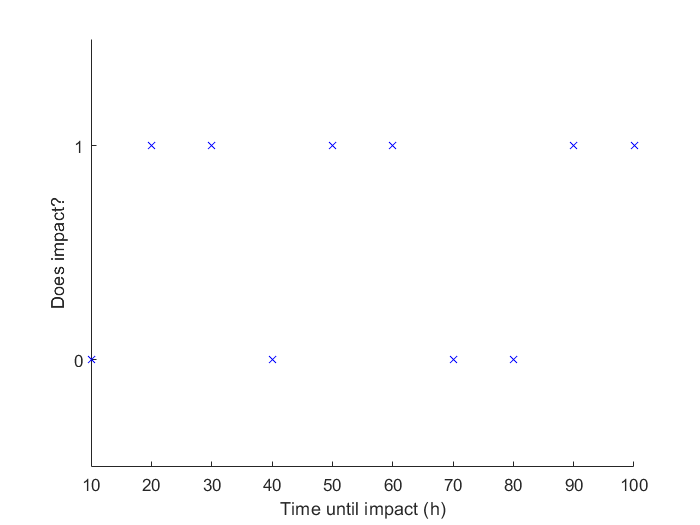


xlabel("Time until impact (h)")

ylabel("Does impact?")
ylim([-0.5 1.5])
yticks([0 1])

hold off

This graph that there are several windows in time where DART will be able to successfully deflect the impactor. The earliest one that happens at t=10 hours.